clear
close all
clc

opengl Hardware

Opgave 7:

Et Bessel-lavpasfilter skal maksimalt dæmpe 3 dB ved 1 kHz, og samtidig må tidsforsinkelsen maksimalt være faldet med 1% i forhold til DC. Filteret skal dæmpe 65 dB ved 10 kHz.

7.1: Bestem den mindste filterorden, som overholder de stillede krav

Først skal findes ordenen, der overholder kravene til lavpasfiltrering.

Ap = 3;
wp = 1000*2*pi;
As = 65;
ws = 10000*2*pi;

N = besselor(Ap,wp,As,ws)

N = 4

Der kræves altså er fjerdeordensfilter for at filtrere. Desuden skal der også overholdes kravet om tidsforsinkelse. For at finde ud af, om dette overholdes, kigges i tabellerne. 

Først findes wn for et fjerdeordensfilter ved 3 dB = 2,13.

Ved at kigge i tabellen for tidsafvigelsen, bemærkes, at wn for 1% er 1,93 for et fjerdeordensfilter. Det er altså nødvendigt at anvende et femteordensfilter, hvis tidsafvigelse for 1% er ved wn = 2,71.

wn for 3 db med et femteordensfilter er 2,42. Ved wn = 2,42 får man altså den korrekte tidsafvigelse og dæmpning.

wn = 2.42;
N = 5;

7.2: Opskriv overføringsfunktionen (denormeret)

%td skal anvendes til at denormere vha. Omega_n
Omega_n = wp/wn

Omega_n = 2.5964e+03

td = 1/Omega_n

td = 3.8515e-04


[K,Z,P] = BESSEL_POLES(td,N);
[num,den] = zp2tf(Z,P,K);
Hsden = tf(num,den)


Hsden =
 
                                 -1.115e20
  ------------------------------------------------------------------------
  s^5 + 3.895e04 s^4 + 7.078e08 s^3 + 7.351e12 s^2 + 4.294e16 s + 1.115e20
 
Continuous-time transfer function.



7.3: Vis amplitude, fasekarakteristik og gruppeløbetid

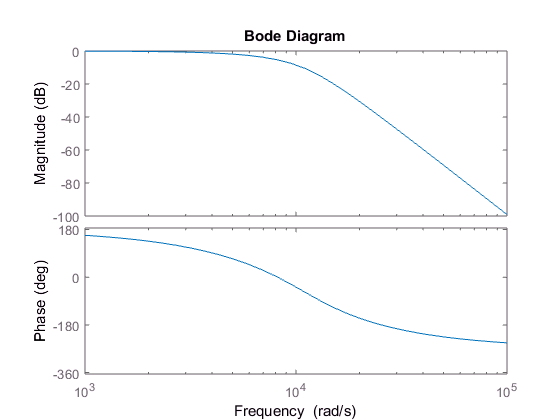

figure(1)
%groupDelaytf(Hsden)
figure(2)
bodeplot(Hsden)